# Identify Shapes Using Machine Learning on Arduino Nano 33 BLE Sense Hardware

This example shows how to use MATLAB® Support Package for Arduino® Hardware to identify shapes using a machine learning algorithm. This example uses the Arduino Nano 33 BLE Sense hardware board with an onboard [LSM9DS1 inertial measurement unit (IMU) sensor](docid:mlsupportpkg#mw_dcb23e4d-75d4-465e-8b7d-e8c6caae9fb4).

To draw the shapes, hold the Arduino board in your palm and move your hand in the air. The IMU sensor captures the linear acceleration and angular rate data along the *X*-, *Y*-, and *Z*-axes. Send this data to the machine learning algorithm which identifies the shape you have drawn and transmits the output over Bluetooth® to the Arduino board. The shape identified by the machine learning algorithm then displays in the MATLAB Command Window.

To access all the files for this example, click **Open Live Script** and download the attached files.

## Prerequisites

- For more information on how to use Arduino hardware with MATLAB, see [Get Started with MATLAB Support Package for Arduino Hardware](docid:matlab_doccenter#mw_cc87085a-8d6a-480b-b0ac-6b7287fe6632).

- For more information on machine learning, see [Get Started with Statistics and Machine Learning Toolbox.](docid:stats_doccenter#bs8t023)

## Required Hardware

- Use an Arduino board with an onboard IMU sensor. This example uses Arduino Nano 33 BLE Sense board that has an onboard LSM9DS1 IMU sensor. This helps you to easily hold the hardware in your hand while you move your hand to draw shapes in the air. Alternatively, you can connect an IMU sensor to any Arduino board that has a sufficiently large memory. For more information on how to connect an IMU sensor to your Arduino board, refer to the sensor datasheet.

- Either connect a Bluetooth dongle to the computer or use the computer's Bluetooth.

## Hardware Setup

Connect the Arduino Nano 33 BLE Sense board to the host computer over Bluetooth. For more information, see [Set up and Configure Arduino Hardware](docid:mlsupportpkg#bvn8yxz-1).

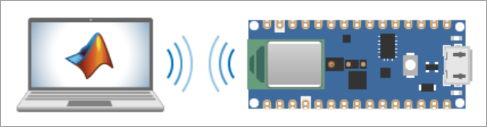

In the Choose Connection Type window under Hardware Setup, set the connection type to Bluetooth.

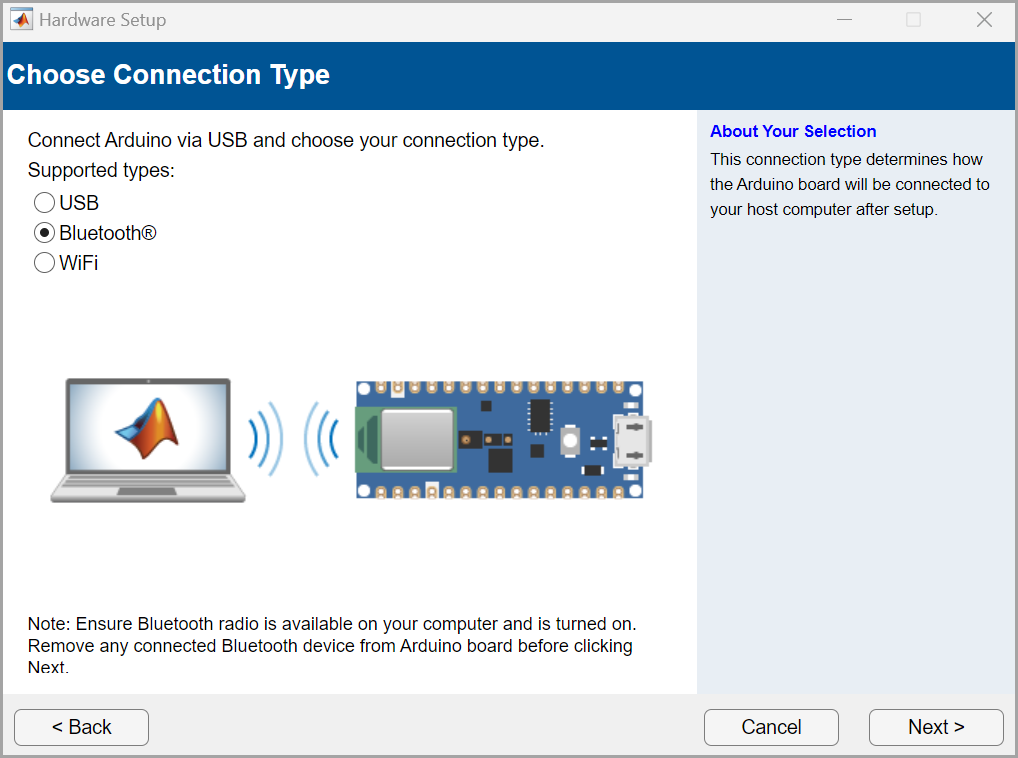

In the Upload Arduino Server window, select the I2C libraries.

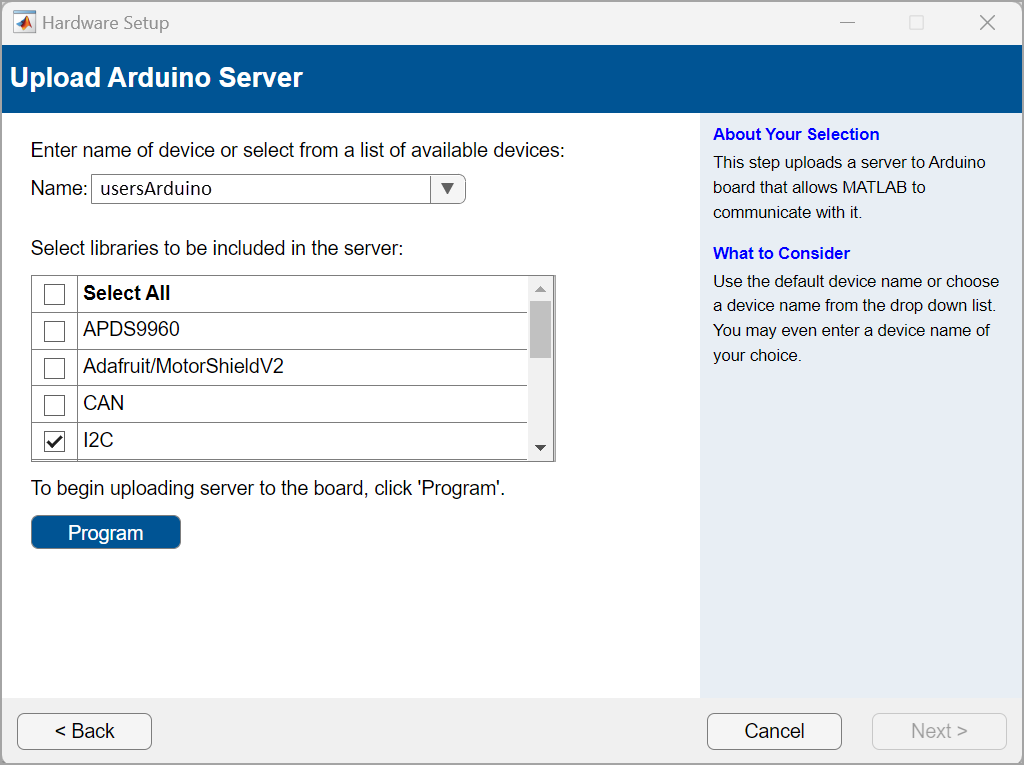

## Capture Data to Train Machine Learning Algorithm

You can either use the `shapes_training_data.mat` file that contains the data set for the circle and triangle shapes or capture the data and create the data set manually. 

### Import Training Data

To use the training data file included with this example, click **Open Live Script** and download the `shapes_training_data.mat` file. The `shapes_training_data` MAT file contains 119 data samples from the accelerometer and gyroscope on the IMU sensor. The 119 samples are grouped into 100 frames, with each frame representing a hand gesture. Each frame has six values from the *X*-, *Y*-, and *Z*-axes of the accelerometer and gyroscope, respectively. The data set contains a total of 11,900 observations for the circle and triangle shapes. 

Load the shapes_training_data.mat file.

load shapes_training_data

### Capture Data Manually

If you are using the s`hapes_training_data.mat` file, skip this section**. **However, if you want to capture the training data for the machine learning algorithm manually, execute the `capture_training_data.m` file. 

In the `capture_training_data.m` file, you can set the acceleration threshold in the `accelerationThreshold` parameter. For this example, set the threshold to `2.5`. For more information on how to adjust the acceleration threshold for an IMU sensor, refer to the sensor datasheet. 

To set up a connection with the Arduino board, create an [arduino](docid:mlsupportpkg#buhpnk9) object and specify name of the board.

To read data from the LSM9DS1 IMU sensor, create an [lsm9ds1](docid:mlsupportpkg#mw_dcb23e4d-75d4-465e-8b7d-e8c6caae9fb4) object and specify the number of samples to read in a single execution of the `read` function. For this example, set the number of samples to read to `119`.

Specify the number of frames to be captured per gesture in the `while` loop. For this example, set that value to `100`.

Hold the Arduino hardware in the palm of your hand and draw a circle in the air. If you want to create a data set of 100 frames for a circle, draw a circle 100 times in the air. Capture the data for the circle shape.

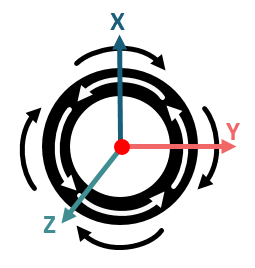

Repeat the procedure for the triangle shape. Capture the data for the triangle shape.

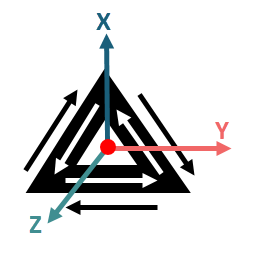

Store the data in the `shapes_training_data.mat` file.

## Extract Feature, Prepare, and Train Data

### Extract

The `gr_script_shapes.m` file included with this example preprocesses the `shapes_training_data.mat` data set file, trains the machine learning algorithm with the data set, and evaluates whether the algorithm accurately predicts the circle and triangle shapes. The MATLAB function in this file performs a five-fold cross validation for the ensemble classifier and computes the validation accuracy of the algorithm. Execute the `gr_script_shapes.m` file. 

run gr_script_shapes.m

The code in the gr_script_shapes.m file extracts features by calculating the mean and the standard deviation of each column in a frame. Considering the data from the *X*-, *Y*-, and *Z*-axes for the accelerometer and the gyroscope and 100 frames per gesture, results in a 100-by-12 matrix of observations for each gesture.

Note: You can configure the number of frames to be captured per gesture in the `while` loop.

### **Prepare**

This example uses 80% of the observations to train a model that classifies two types of shapes and 20% of the observations to validate the trained model. Use [`cvpartition`](docid:stats_ug#brxwayf-1) to partition 20% of the data for the test data set.

The training variables are visible in the **Workspace** pane in MATLAB.

**Train Classification Model **

Train the classification model using the ensemble classifier.

**Validate Classifier**

Perform five-fold cross validation for the ensemble classifier and compute the validation accuracy to evaluate the performance of test data. 

## Predict Shape

Run this MATLAB code to predict the shape. 

% Create an arduino object with Bluetooth connection
aObj = arduino("usersArduino");  % Change this to required Bluetooth name or address 

% Create LSM9DS1 object
imuObj = lsm9ds1(aObj,"Bus",1,"SamplesPerRead",119,'Bus',1);
disp('Start capturing gesture data.');

% Set the acceleration threshold
accelerationThreshold = 2.5;

% Predict the shapes for 10 seconds
tic;
while (toc<10)
    % Read the acceleration
    accel = readAcceleration(imuObj);
    
    %Sum up absolute values of acceleration
    aSum = sum(abs(accel))/9.8;
    
    %Capture values if there is significant motion
    if aSum >= accelerationThreshold
        %Read IMU sensor data
        imudata  =  read(imuObj);
        imudatatable = timetable2table(imudata);
        
        %Save values in data variable
        testGesture = [imudatatable.Acceleration/9.8 rad2deg(imudatatable.AngularVelocity)];
        
        % Get the features of the captured gesture
        feature1 = mean(testGesture);
        feature2 = std(testGesture);
        features = [feature1 feature2];
        
        % Predict the gesture
        y = predict(ensMdl,features);
        if y == 1
            disp('Circle');
        elseif y == 2
            disp('Triangle');
        end
    end
end
release(imuObj);
clear imuObj aObj;

*Copyright 2023 The MathWorks, Inc.*